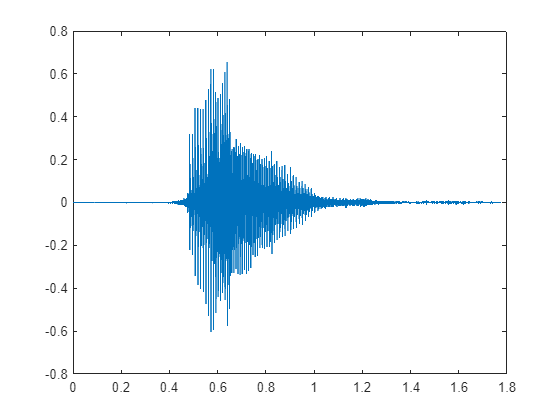

[y,Fs] = audioread("human_voice.wav");
t = linspace(0,length(y)/Fs,length(y));
t= t';
figure(1)
title("original signal")
plot(t,y)

% 
% win = hann(100,'periodic');
% [S,F,T] = stft(y,Fs,"window", win);
% smag = mag2db(abs(S));
% pcolor(seconds(T), F, smag)
% shading flat
% colorbar
% clim(max(smag(:)+[-60 0 ]))

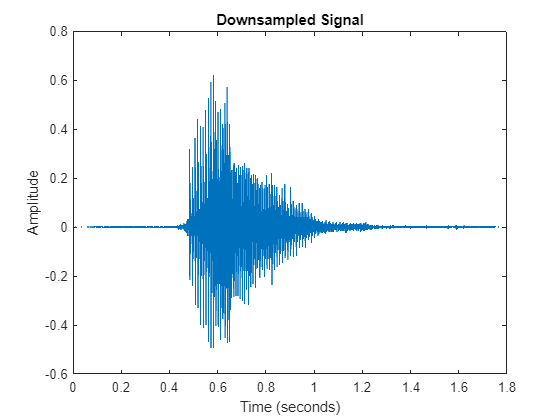

[y, Fs] = audioread("human_voice.wav");

% Downsample manually by selecting every 6th sample
n = 6; % Downsample factor
compressed = y(1:n:end, :);

% Adjust the time vector to reflect the new sampling rate
Fs_new = Fs / n;
tow = linspace(0, length(compressed)/Fs_new, length(compressed));

% Plot the downsampled signal
figure(2)
plot(tow, compressed)
title("Downsampled Signal")
xlabel('Time (seconds)')
ylabel('Amplitude')